GPU Check

gpuDeviceTable

ans = 1×5 table
    Index              Name               ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3070"          "8.6"               true              true      


Set GPU

gpuDevice(1)

ans =   CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589279232 (8.59 GB)
      AvailableMemory: 7443034112 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

Parameters

name = "GoogleNet"

name = "ArticleNet"

dataset_size = 2000

dataset_size = 2000

batch_size = 40

batch_size = 40

epochs = 10

epochs = 10

model_directory = strcat("CNN/", name, "/MathLab_Data")

model_directory = "CNN/ArticleNet/MathLab_Data"

mkdir(model_directory)

mkdir(model_directory + "/training")

mkdir(model_directory + "/validation")

mkdir(model_directory + "/final_test_results")

Loading dataset

files = dir();
file_names = {files.name};

if any(file_names(:) == "Mushroom dataset") == 0
    disp("Dataset file not found, unzipping...")
    unzip("Mushroom dataset.zip", "Mushroom dataset/")
    disp("Done")
else
    disp("Dataset file found")
end

Dataset file found



disp("Loading dataset files...")

Loading dataset files...


src_folder = "Mushroom dataset/cnn";
dataset = imageDatastore(src_folder, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");
disp("Done")

Done



classNames = categories(dataset.Labels)

classNames = 2×1 cell array
    {'Edible'   }
    {'Poisonous'}


numClasses = numel(classNames);

K Group Partition

k_groups = cvpartition(dataset_size, "KFold", 10)

k_groups = K-fold cross validation partition
   NumObservations: 2000
       NumTestSets: 10
         TrainSize: 1800  1800  1800  1800  1800  1800  1800  1800  1800  1800
          TestSize: 200  200  200  200  200  200  200  200  200  200
          IsCustom: 0

Mean accuracy setup

acc_history = zeros(1, 10)

acc_history =      0     0     0     0     0     0     0     0     0     0


Train network with K-Groups

for i = 1:(k_groups.NumTestSets)

    disp("K : " + i)

    k_train_index = training(k_groups, i);
    k_test_index = test(k_groups, i);

    dataset_train = imageDatastore(dataset.Files(k_train_index), "Labels", dataset.Labels(k_train_index));
    dataset_val = imageDatastore(dataset.Files(k_test_index), "Labels", dataset.Labels(k_test_index));

    net = imagePretrainedNetwork("googlenet", NumClasses=numClasses);
    options = trainingOptions("sgdm", ...
        MiniBatchSize=batch_size, ...
        MaxEpochs=epochs, ...
        Metrics="accuracy", ...
        InitialLearnRate=1e-3, ...
        ValidationFrequency=1, ...
        Verbose=0, ...
        ValidationData=dataset_val, ...
        Plots="training-progress");

    [net, info]= trainnet(dataset_train, net, "crossentropy", options);
    acc_column = info.TrainingHistory(:, 5);
    acc_history(i) = table2array(acc_column(end, :))
    
    train = info.TrainingHistory;
    writetable(train, model_directory + "/training" + "/train" + "K" + i + ".csv");

    val = info.ValidationHistory;
    writetable(val, model_directory + "/validation" + "/val" + "K" + i + ".csv");

end

K : 1


acc_history =     30     0     0     0     0     0     0     0     0     0


K : 2


acc_history =     30    70     0     0     0     0     0     0     0     0


K : 3


Unable to perform assignment because the left and right sides have a different number of elements.

Error in deep.TrainingInfo>iCreateTrainingHistory (line 121)
    value(mask) = trainingData(:,2);

Error in deep.TrainingInfo.createTrainingInfo (line 90)
            trainingHistory = iCreateTrainingHistory(monitorConfig,

Load final train, test set

files = dir();
file_names = {files.name};

if any(file_names(:) == "FinalTrainTestSet") == 0
    disp("Final dataset file not found, unzipping...")
    unzip("FinalTrainTestSet.zip", "FinalTrainTestSet/")
    disp("Done")
else
    disp("Final dataset file found")
end

Final dataset file found



disp("Loading final dataset train...")

Loading final dataset train...



src_folder = "FinalTrainTestSet/dataset_train/cnn";
final_dataset_train = imageDatastore(src_folder, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

disp("Loading final dataset test...")

Loading final dataset test...



src_folder = "FinalTrainTestSet/dataset_test/cnn";
final_dataset_test = imageDatastore(src_folder, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

disp("Done")

Done


Train model

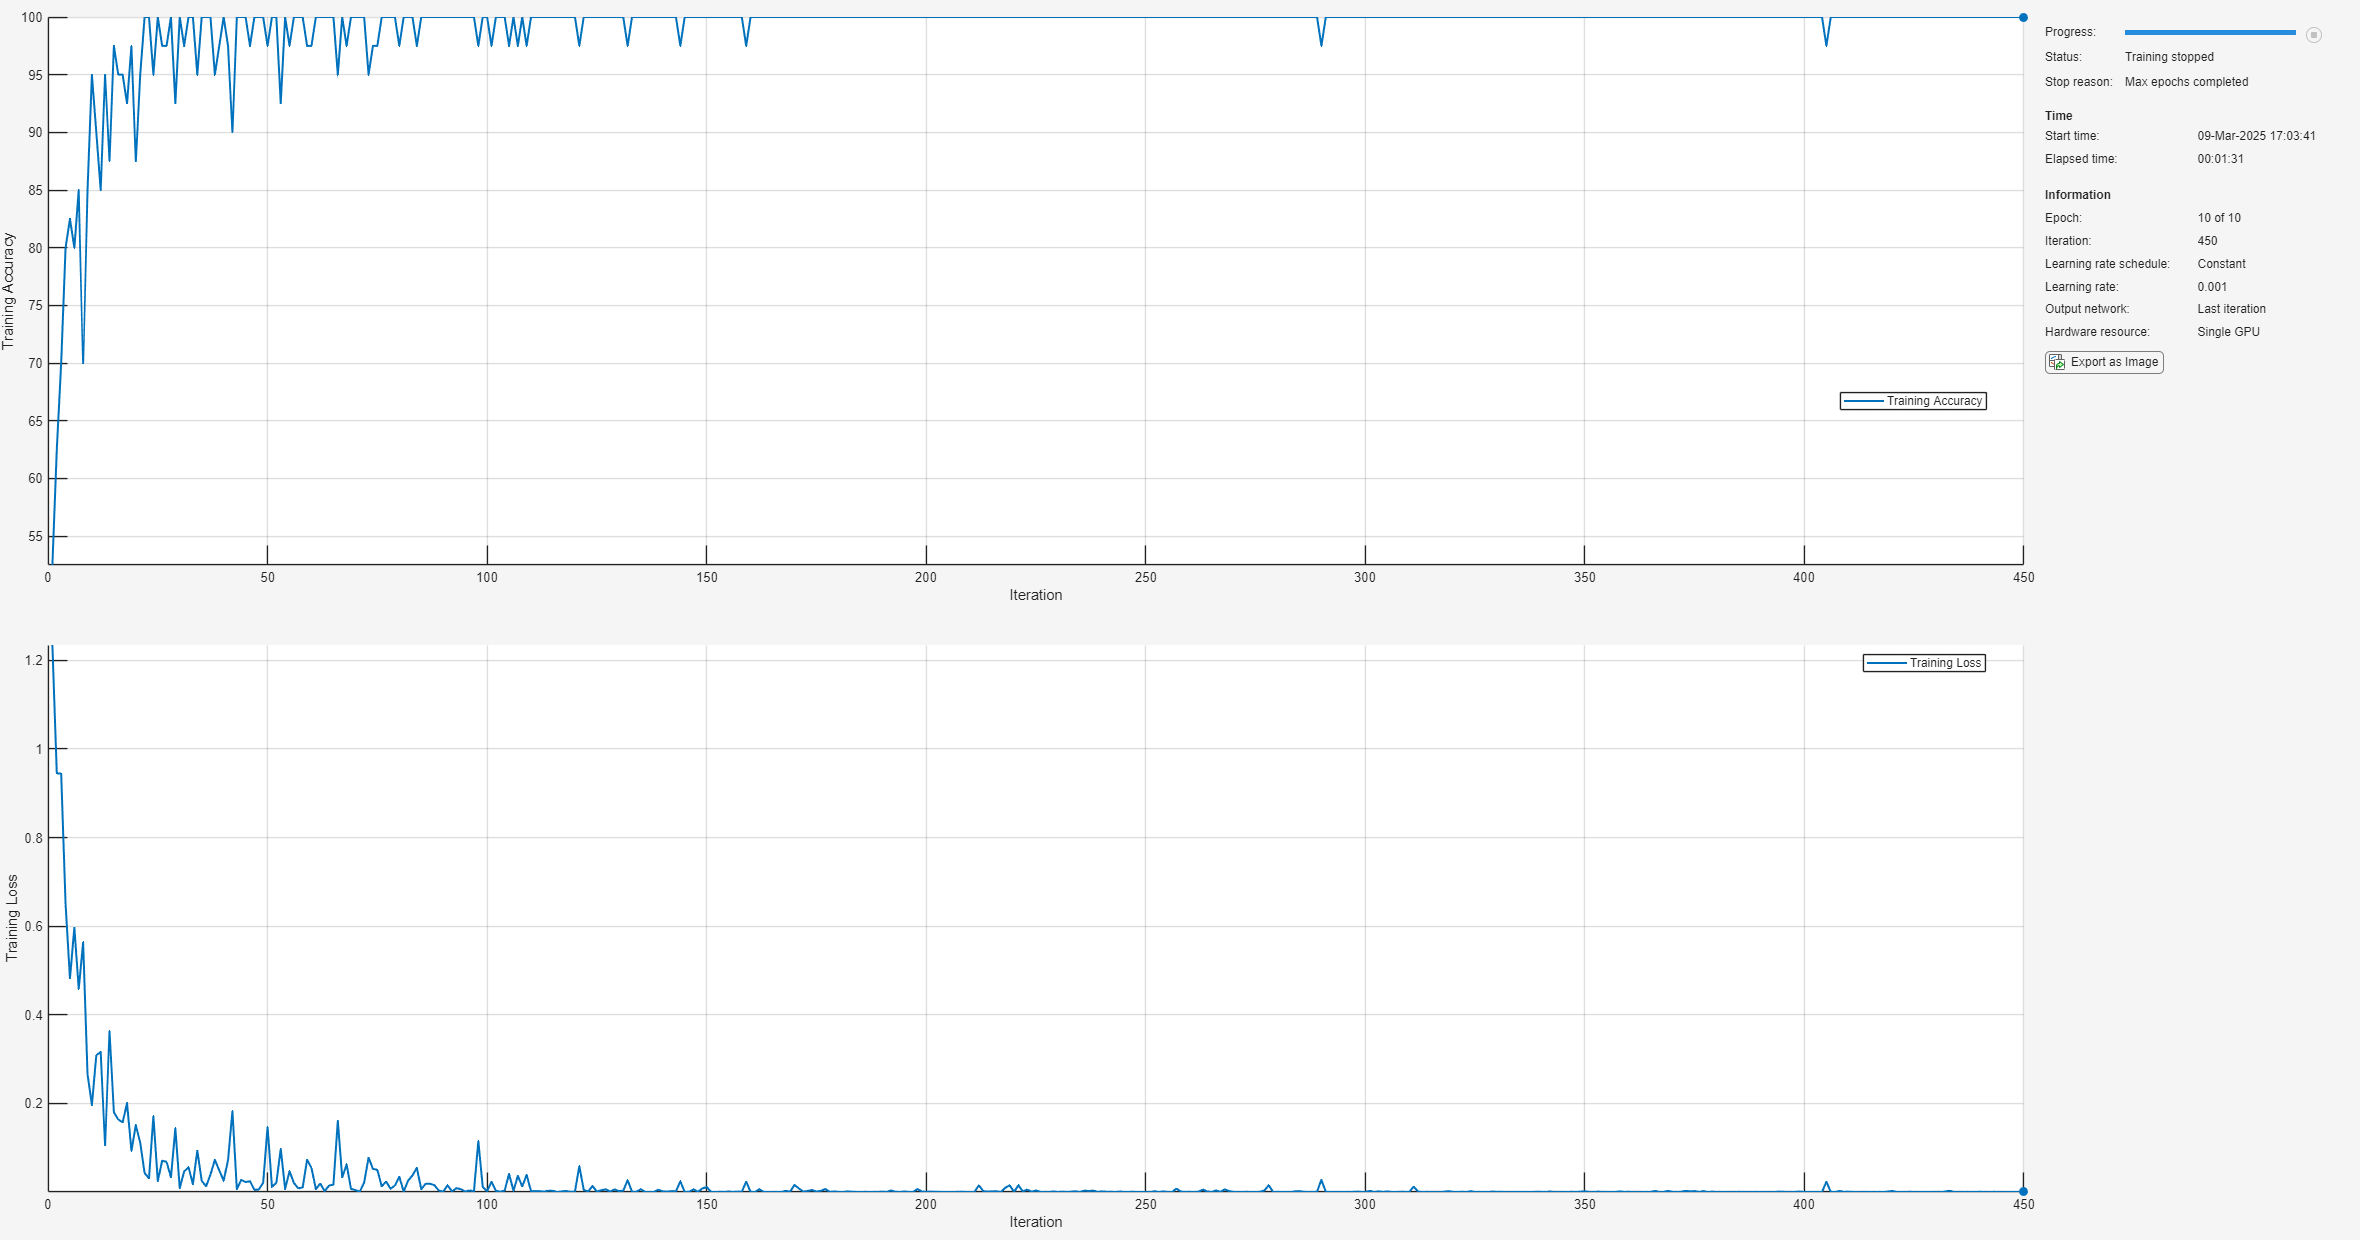

net = imagePretrainedNetwork("googlenet", NumClasses=numClasses);
    options = trainingOptions("sgdm", ...
        MiniBatchSize=batch_size, ...
        MaxEpochs=epochs, ...
        Metrics="accuracy", ...
        InitialLearnRate=1e-3, ...
        Verbose=0, ...
        Plots="training-progress");

[net, info]= trainnet(final_dataset_train, net, "crossentropy", options);

Time : 

AlexNet : 45s

ResNet50 : 3 min 13s

GoogleNet : 1 min 31s

Compute predictions

scores = minibatchpredict(net, final_dataset_test);
y_predicted = scores2label(scores, classNames)

y_predicted = 200×1 categorical array
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 


y_test = final_dataset_test.Labels

y_test = 200×1 categorical array
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 
     Edible 


Export predictions

pred = array2table(y_predicted);
test = array2table(y_test);

disp("Exporting final results...")

Exporting final results...



writetable(pred, model_directory + "/final_test_results/y_predicted.csv");
writetable(test, model_directory + "/final_test_results/y_test.csv");

disp("Done")

Done


Deep dreaming

analyzeNetwork(net)

AlexNet : fc7

ResNet50 : fc1000

GoogleNet : loss3-classifier

layer = "loss3-classifier";
channels = 1:2;

I = deepDreamImage(net, layer, channels, ...
    PyramidLevels=6, ...
    Verbose=1);

Error using deepDreamImage (line 153)
Expected input number 3, channel, to be an array with all of the values <= 2.

imshow(I(:,:,:,2))

imwrite(I(:,:,:,2), "CNN/" + name + "/" + "DP1.png")